## Path names

fn_base = 'Z:\\All_Staff';
gk_fn = fullfile(fn_base, 'home\gloria\Analysis\2P');
tc_fn = fullfile(gk_fn, '\tutorial'); 
mworks_fn = fullfile(fn_base, 'Behavior\Data');
fnout = fullfile(gk_fn, '\oriAnalysis'); 

## Specific experiment information

date = '220428'; 
ImgFolder = '003'; 
time = '1115';
mouse = 'i2516'; 
mouse_mworks = 'i''i2516''';
frame_rate = 15.5; 
run_str = catRunName(ImgFolder, 1); 
datemouse = [date '_' mouse];
datemouserun = [date '_' mouse '_' run_str];

## Load mWorks and TC data

Load mworks data and neuropil-subtracted time course data from the tutorial

fName = fullfile(mworks_fn, ['data-' mouse_mworks '-' date '-' time '.mat']);
load(fName);

CD = fullfile(tc_fn, datemouse, datemouserun);
cd(CD);
timecourse = [datemouserun '_TCs.mat'];
load(timecourse); 

## 1. Transform TCs into trial matrix

    a. Reshape data stack to segregate trials 

    First need to know how many frames per trial and how many trials

nOn = input.nScansOn; % on trials
nOff = input.nScansOff; % off trials
nFramesPerTrial = nOn+nOff;
ntrials = size(input.tGratingDirectionDeg,2);
ncells = size(npSub_tc,2);

    Reshape npSub_tc (nframes x ncells) into a matrix that is nFrames/Trial x nTrials x ncells

F_matrix = reshape(npSub_tc,[nFramesPerTrial, ntrials, ncells]);
fprintf(['Size of F_matrix is ' num2str(size(F_matrix))])

Size of F_matrix is 90  640  171

    b. Create baseline F (F0) matrix by averaging from last half of off period

F0_matrix = mean(F_matrix(nOff/2:nOff,:,:)); 

    c. Find dF/F for each trial

dFoF = (F_matrix-F0_matrix)./F0_matrix;

## 2. Identify cells that are significantly responsive to at least one orientation

    a. Define two analysis windows- base_win and resp_win

base_win = [30:59];
resp_win = [61:90];

    b. Create two matrices: base (a ncells x ntrials matrix with the average response during the baseline window) and resp (a ncells x ntrials matrix with the average response during the response window).

base = squeeze(mean(dFoF(base_win,:,:))); 
resp = squeeze(mean(dFoF(resp_win,:,:))); 

    c. Create a “for” loop where you loop through each orientation and select the set of trials for that orientation and use a “ttest” to compare the baseline and stimulus response across those trials.

Dir = celleqel2mat_padded(input.tGratingDirectionDeg); % directions of each trial
nDirs = unique(Dir); % what are the directions
Ori = Dir;
Ori(Ori>=180) = Ori(Ori>=180) - 180; % turn Dirs into Oris by subtracting 180 from those over 180
Oris = unique(Ori); % what are the orientations
nOris = length(Oris); % how many orientations
bonferroni = (.05/(nOris-1)); % bonferroni correction for multiple comparisons(???)

h = zeros(nOris,ncells); % creates a matrix for outcome of ttest (hypothesis)
p = zeros(nOris,ncells); % creates a matrix for outcome of ttest (p-values)
avg_resp = zeros(nOris,ncells); % average response of each cell to each orientation
std_err = zeros(nOris,ncells); % standard error for avg response

for i = 1:nOris
    ind = find(Ori == Oris(i)); % array of all trials for specific orientation
    b = base(ind,:); % df/f for baseline window on trials of specific orientation
    r = resp(ind,:);  %df/f for response window on trials of specific orientation
    [h(i,:) p(i,:)] = ttest(b,r,'Alpha',bonferroni,'tail','left'); %t test of bl vs resp means for given orientation
    avg_resp(i,:) = mean(r,1); % avg response of each cell at each orientation
    std_err(i,:) = (std(r,1))/(sqrt(length(Oris))); % std error of response at each orientation
end

    How many cells are significant for at least one orientation?

sig_ori = zeros(1,ncells);

for i = 1:ncells
    sig_ori(i) = sum(h(:,i)); %sum of all orientation significance values (0 or 1) for each cell
end

n_sig_ori = sum(sig_ori>=1)

n_sig_ori = 170

    How many are significant if you don’t do the bonferonni correction (alpha  = 0.05)? Why do we use this correction?

h_2 = zeros(nOris,ncells); % creates a matrix for outcome of ttest (hypothesis)
p_2 = zeros(nOris,ncells); % creates a matrix for outcome of ttest (p-values)

for i = 1:nOris
    ind = find(Ori == Oris(i));
    b = base(ind,:); 
    r = resp(ind,:);
    [h_2(i,:) p_2(i,:)] = ttest(b,r, 'tail','left'); 
end

sig_ori_2 = zeros(1,ncells);

for i = 1:ncells
    sig_ori_2(i) = sum(h_2(:,i)); 
end

n_sig_ori_2 = sum(sig_ori_2>=1)

n_sig_ori_2 = 171

## 3. Plot the average tuning curve for all cells in the field of view

i.e. each cell’s stimulus response to each orientation

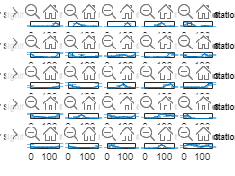

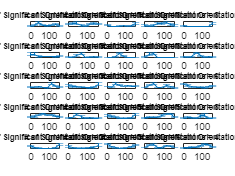

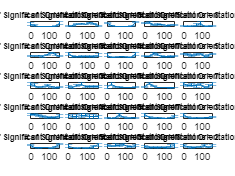

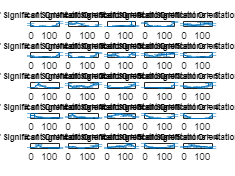

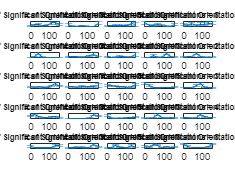

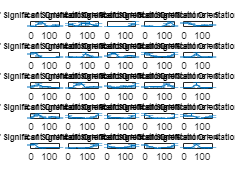

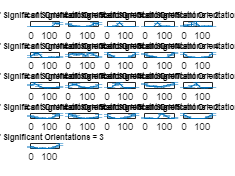

figure;
if ncells<25
    [n n2] = subplotn(ncells);
else
    [n n2] = subplotn(25);
end

start = 1; % which figure you're on
x = 0; % which subplot in the designated figure you're on
for i = 1:ncells
    if start > 25
        start = 1;
        x = x+1;
        figure;
    end
    subplot(n,n2,i-(x.*25)) % which subplot position
    errorbar(Oris,avg_resp(:,i),std_err(:,i)) % plot with error bars of all orientations for a given cell
    hold on
    title(['# of Significant Orientations = ', num2str(sig_ori(i))], "FontSize", 6.5)
    start = start+1;
end

## 4. Fit data with a von Mises function

    a. Use your baseline and response matrices to create a new matrix of baseline subtracted responses for each trial (resp-base).

bl_sub_resp = resp-base;

    b. Make a for loop where you loop through each cell and use the function miaovonmisesfit_ori. The inputs should be the orientations that you presented (theta, 1 x nori) and the average response of each cell to each orientation.

clear b r
ori_rads = deg2rad(Oris); % change theta from degrees to radians
b = zeros(1,ncells);
r = zeros(1,ncells);
k1 = zeros(1,ncells); % the sharpness of the orientation tuning
u1 = zeros(1,ncells); % the preferred orientation
sse = zeros(1,ncells); % sum of squared error
R_square = zeros(1,ncells);

for i = 1:ncells
    [b(i) k1(i) r(i) u1(i) sse(i) R_square(i)] = miaovonmisesfit_ori(ori_rads,avg_resp(:,i));
end

    c.  Then you can add the fit to your plot of each cell (from 2a-d).

y_fit = zeros(180,ncells);
new_oris = deg2rad(0:1:179);

for i = 1:ncells
    b_fit = b(i);
    R1_fit = r(i);
    k1_fit = k1(i);
    u1_fit = u1(i);
    y_fit(:,i) = b_fit+R1_fit.*exp(k1_fit.*(cos(2.*(new_oris-u1_fit))-1));
end

    d. What is the preferred orientation of each cell?

[pref_ori_val pref_ori_deg] = max(y_fit,[],1);

figure;
if ncells<25
    [n n2] = subplotn(ncells);
else
    [n n2] = subplotn(25);
end

start = 1; % which figure you're on
x = 0; % which subplot in the designated figure you're on
for i = 1:ncells
    if start > 25
        start = 1;
        x = x+1;
        figure;
    end
    subplot(n,n2,i-(x.*25)) % which subplot position
    errorbar(Oris,avg_resp(:,i),std_err(:,i)) % plot with error bars of all orientations for a given cell
    hold on
    plot(y_fit(:,i)); % plot the fits
    vline(pref_ori_deg(i),'black'); % indicate preferred orientation
    title(['# of Significant Orientations = ', num2str(sig_ori(i))], "FontSize", 6.5)
    start = start+1;
end
hold off;

## 5. Bootstrap

    a.-b. Create a for loop that will cycle through your von Mises fit 1000 times. Before each fit, resample the trials (with replacement) that you use to measure the average orientation.

bootstrap = 10;

avg_resp_resample = zeros(nOris,ncells);
std_err_resample = zeros(nOris,ncells);
y_fit_resample = zeros(length(new_oris),ncells);
pref_ori_resample = zeros(bootstrap,ncells);

for cycle = 1:bootstrap
    for i = 1:nOris % resampling random trials for each orientation
        Ori_resample = randsample(find(Ori == Oris(i)),length(find(Ori == Oris(i))),1);
        b_resample = base(Ori_resample,:);
        r_resample = resp(Ori_resample,:);
        avg_resp_resample(i,:) = mean(r_resample,1);
        std_err_resample(i,:) = (std(r_resample,1))/(sqrt(length(Ori_resample)));
    end
% Still within the loop, use your ncells x nori matrix to fit each cell using miaovonmises_ori to get the parameters.
    for c = 1:ncells;
        [b(c) k1(c) r(c) u1(c) sse(c) R_square(c)] = miaovonmisesfit_ori(ori_rads,avg_resp_resample(:,c));
        b_tmp = b(c);
        R1_tmp = r(c);
        k1_tmp = k1(c);
        u1_tmp = u1(c);
        y_fit_resample(:,c) = b_tmp+R1_tmp.*exp(k1_tmp.*(cos(2.*(new_oris-u1_tmp))-1));
% For each loop find the preferred orientation of each cell so that you end up with a ncells x nbootstraps variable of the preferred orientations found with each fitting procedure.
        pref_ori_resample(cycle,c) = rad2deg(u1(c));
        pref_ori_resample(pref_ori_resample<0) = pref_ori_resample(pref_ori_resample<0)+180;
    end; 
end

    e. To determine the reliability of the preferred orientation, subtract the preferred orientation from the original measure with all trials included (from #3) from the preferred orientations measured on each of the 1000 bootstraps, and take the absolute value (to get the set of differences from actual). Sort these values in ascending order, and find the value in the 900th spot (this will be the 90th percentile).

pref_ori_90prct = prctile(sort(abs(pref_ori_resample - pref_ori_deg)),90);

    f. Find those cells where the 90th percentile is less than 22.5.

reliably_fit_cells = pref_ori_90prct<22.5;
n_reliably_fit = sum(reliably_fit_cells);

## 6. Summarize the responsivity and reliability of the imaged cells

    a. Make a bar plot with number of cells, number of responsive cells, and number of cells reliably fit by von Mises

figure;
x_lab = categorical(["Total", "Responsive to at least one ori", "Reliably fit"]);
x_lab = reordercats(x_lab,["Total", "Responsive to at least one ori", "Reliably fit"]); %defines mathematical order of the categories for the histogram function
bar(x_lab, [ncells, n_sig_ori, n_reliably_fit])
ylabel("Number of Cells")

    b. Make a histogram of the distribution of preferred orientations (u1) and sharpness (k1) of orientation tuning for the reliably fit cells.

figure;
pref_ori_reliablyfit = pref_ori_deg(reliably_fit_cells);
sharpness_reliably_fit = k1(reliably_fit_cells);
subplot(1,2,1)
histogram(pref_ori_reliablyfit, 8)
title('Preferred Orientations')
subplot(1,2,2)
histogram(sharpness_reliably_fit, 8)
title('Sharpness of Tuning')